# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

**In-class Worksheet (12/3/2025)**

## The Model.

The optimization problem is


$$\underset{\{c_t\}_{t=0}^{T-1},\{a_t\}_{t=1}^{T-1}}{\text{max}}U= \sum_{t=0}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } a_{t+1} = (1+r)(a_t + y_t - c_t) \text{ ,}\end{array} $$



$$\[
y_t =
\begin{cases} 
\bar{y} & \text{if } t < t_r, \\
\kappa \bar{y} & \text{if } t \geq t_r,
\end{cases}
\]$$



$$a_0 \text{ given , }$$



$$a_T = 0,$$



$$c_t > 0\text{ .}$$


## Recursive Formulation.

The recursive formulation is


$$U_t(a_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


 
$$\begin{array}{r l} \text{s.t. } a_{t+1} = (1+r)(a_t + y_t - c_t) \text{ ,}\end{array} $$



$$\[
y_t =
\begin{cases} 
\bar{y} & \text{if } t < t_r, \\
\kappa \bar{y} & \text{if } t \geq t_r,
\end{cases}
\]$$



$$a_0 \text{ given , }$$



$$a_T = 0,$$



$$c_t > 0\text{ .}$$


We have:


$$c_t = -\frac {a_t+1}{1 + r} +a_t+ y_t$$


Substituting the constraint gives


$$V_t(W_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{\left(\frac{-a_{t+1}}{1+r}+a_t + y_t\right)^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/USER/Documents/GitHub/Dynamic-Macro_Inclass-code'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is /Users/USER/Documents/GitHub/Dynamic-Macro_Inclass-code 



## Set the parameters and generate the state space.

Calls: model.m.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration (VFI) on the grid.

Calls: solve.m, and model.m.

t = cputime;
sol = solve.cs_model_fin(par); % Solve the model using Value Function Iteration.

------------Beginning Backward Induction.------------

------------End of Backward Induction.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.1562 seconds.


## Simulate Model.

Calls: simulate.m

sim = simulate.asset(par,sol); % Simulate the model.

## Plot the policy functions.

Calls: my_graph.m.

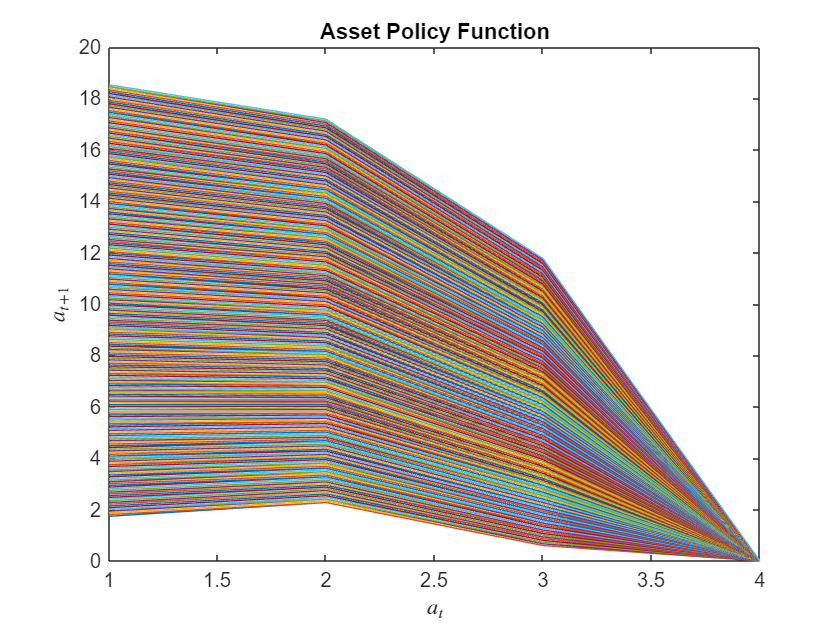

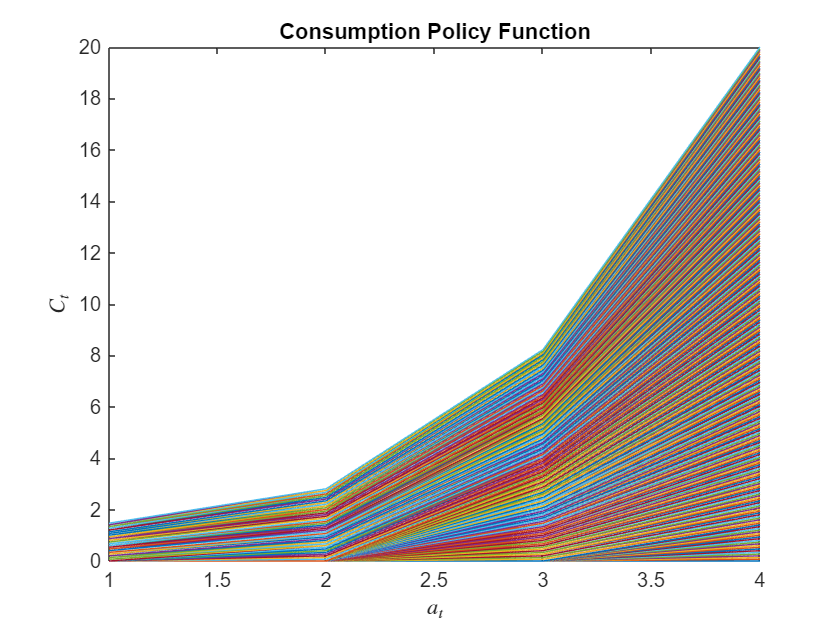

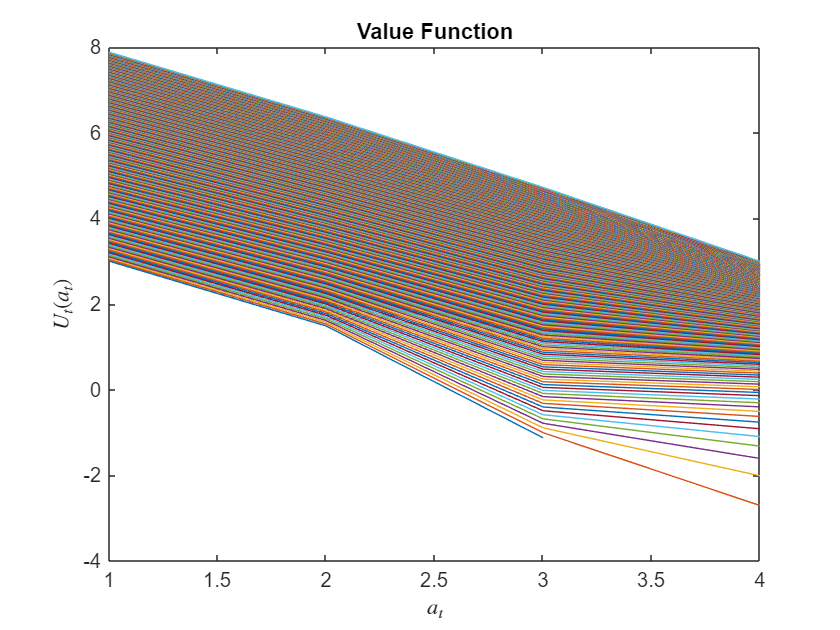

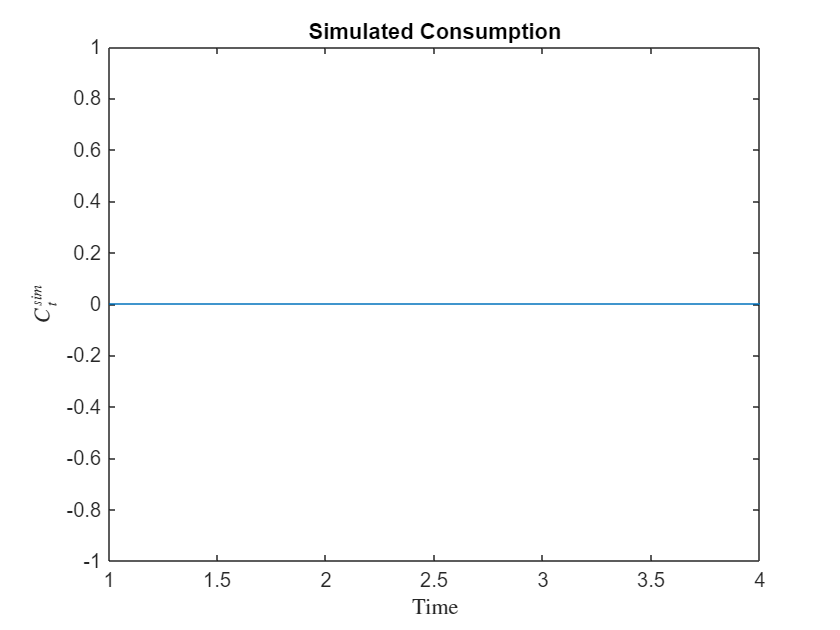

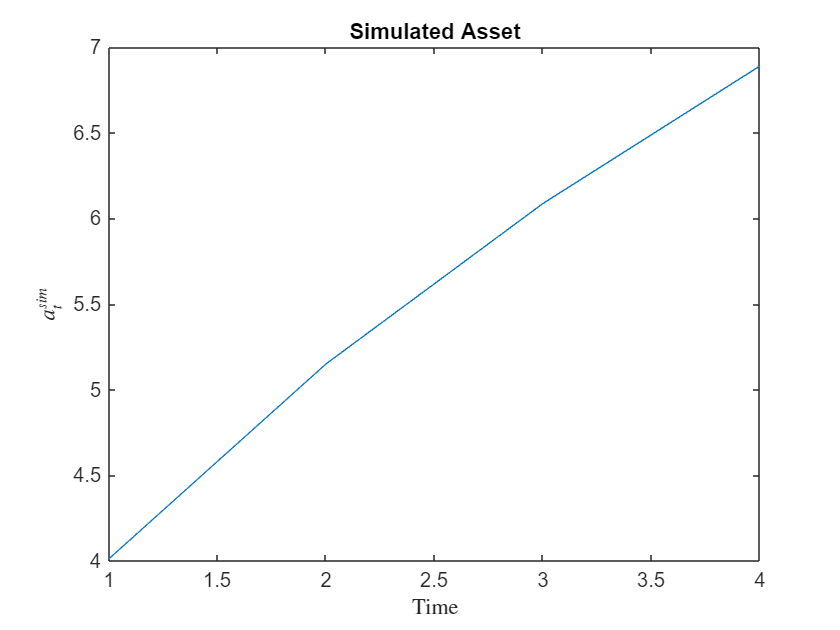

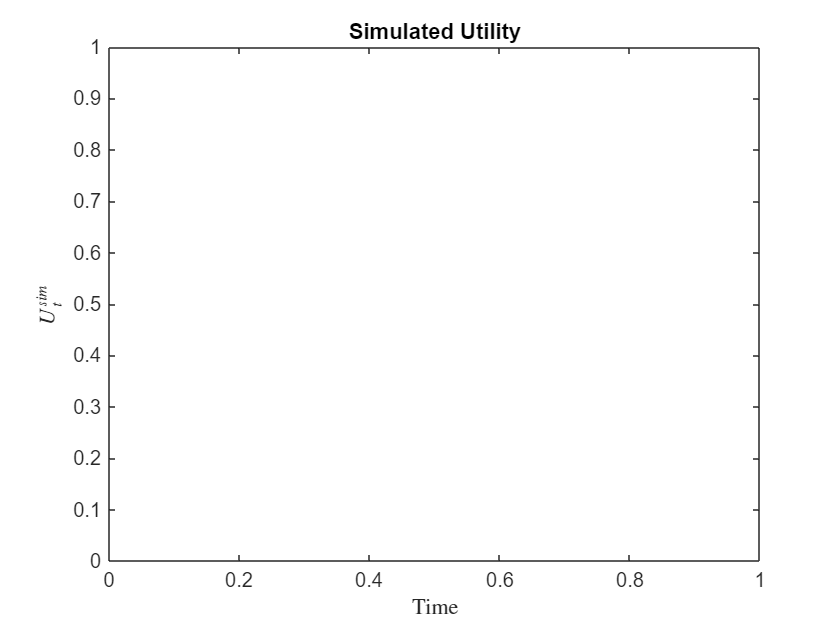

my_graph.plot_policy(par,sol,sim,figout)